**Clearing Matlab**

% Clearing MATLAB 
clear all; clc; close all;

## Setting Up Data

% Importing dataset 

% Import data from text file
BostonHousing = readtable("C:\Users\ajryt\OneDrive\Documents\MATLAB\Business Analytics\BostonHousing.csv");

% Display results
BostonHousing

BostonHousing = 506×14 table
     crim       zn     indus    chas     nox      rm      age      dis      rad    tax    ptratio      b       lstat    medv
    _______    ____    _____    ____    _____    _____    ____    ______    ___    ___    _______    ______    _____    ____

    0.00632      18    2.31      0      0.538    6.575    65.2      4.09     1     296     15.3       396.9     4.98      24
    0.02731       0    7.07      0      0.469    6.421    78.9    4.9671     2     242     17.8       396.9     9.14   

data = table2array(BostonHousing);

 [Observations,Variables] = size(BostonHousing)

Observations = 506

Variables = 14

 % Set the random number generator seed for reproducibility
seed = 42; % You can choose any integer value
rng(seed);

## **2.2 Data Understanding and Data Preparation**

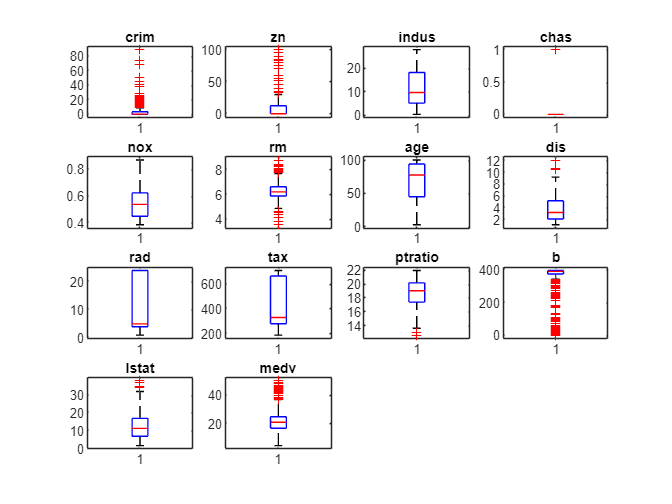

% Creating boxplot
figure;

% Loop through each variable
for i = 1:Variables 
    subplot(4, 4, i); % Create subplots in a 4x4 grid
    boxplot(data(:,i));
    title(BostonHousing.Properties.VariableNames(i));
end

for i = 1:Variables
    q1 = quantile(data(:,i), 0.25);
    q3 = quantile(data(:,i), 0.75);
    irq = q3 - q1;
    % Find outliers
    outliers = data(:,i) < (q1 - 1.5 * irq) | data(:,i) > (q3 + 1.5 * irq);
    perc = sum(outliers) * 100.0 / numel(data(:,i));
    fprintf('Variable %s outliers = %.2f%%\n', BostonHousing.Properties.VariableNames{i}, perc);
end

Variable crim outliers = 13.04%
Variable zn outliers = 13.44%
Variable indus outliers = 0.00%
Variable chas outliers = 6.92%
Variable nox outliers = 0.00%
Variable rm outliers = 5.93%
Variable age outliers = 0.00%
Variable dis outliers = 0.99%
Variable rad outliers = 0.00%
Variable tax outliers = 0.00%
Variable ptratio outliers = 2.96%
Variable b outliers = 15.02%
Variable lstat outliers = 1.19%
Variable medv outliers = 7.31%


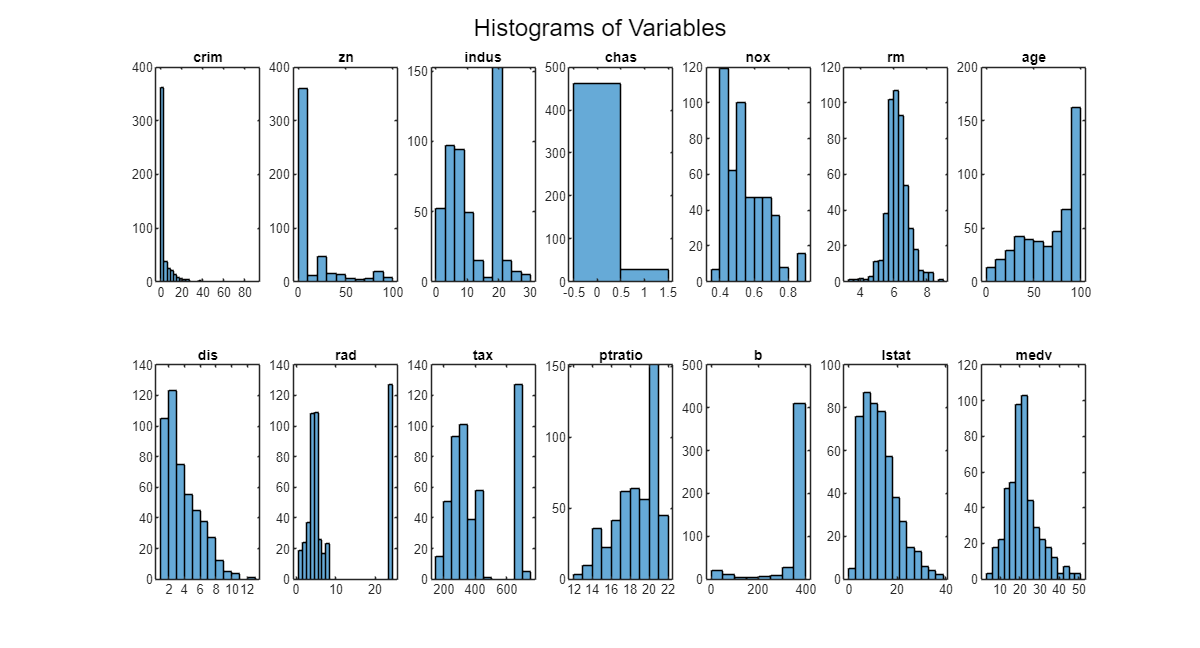

% Find rows where 'MEDV' column value is less than 50.0 to remove outliners
data = data(data(:,end) < 50.0, :);

% Plotting distribution of data'
fig = figure;
set(fig, 'Position', [0, 0, 1200, 600]); % Set figure size

num_cols = 7;
num_rows = ceil(size(data, 2) / num_cols);

for i = 1:Variables
    subplot(num_rows, num_cols, i);
    histogram(data(:, i));
    title(BostonHousing.Properties.VariableNames(i));
end

sgtitle('Histograms of Variables');

% Adjust layout
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% Compute mean, median, minimum, maximum, and quartiles for each variable
means = mean(data)

means =     3.6432   11.1122   11.1131    0.0592    0.5543    6.2455   68.2790    3.8345    9.5143  408.0020   18.5200  355.8554   12.9240   21.6359


medians = median(data)

medians =     0.2475         0    9.6900         0    0.5380    6.1850   76.8000    3.2759    5.0000  330.0000   19.1000  391.7700   11.6750   20.9000


mins = min(data)

mins =     0.0063         0    0.7400         0    0.3850    3.5610    2.9000    1.1370    1.0000  187.0000   12.6000    0.3200    1.9800    5.0000


maxs = max(data)

maxs =    88.9762  100.0000   27.7400    1.0000    0.8710    8.7800  100.0000   12.1265   24.0000  711.0000   22.0000  396.9000   37.9700   48.8000


q1 = quantile(data, 0.25)

q1 =     0.0820         0    5.1900         0    0.4490    5.8800   44.4000    2.1107    4.0000  280.0000   17.4000  375.8700    7.3400   16.7000


q3 = quantile(data, 0.75)

q3 =     3.6737   12.5000   18.1000         0    0.6240    6.5790   93.9000    5.2146   24.0000  666.0000   20.2000  396.3300   17.1200   24.7000


% Calculate and display the correlation matrix
corrMatrix = corr(data);
disp(corrMatrix);

    1.0000   -0.1991    0.4081   -0.0642    0.4205   -0.2193    0.3538   -0.3822    0.6274    0.5837    0.2871   -0.3845    0.4618   -0.4501
   -0.1991    1.0000   -0.5271   -0.0539   -0.5121    0.3105   -0.5632    0.6732   -0.3077   -0.3029   -0.3818    0.1761   -0.4221    0.4046
    0.4081   -0.5271    1.0000    0.0358    0.7652   -0.4124    0.6380   -0.7103    0.5961    0.7177    0.3877   -0.3634    0.6365   -0.6000
   -0.0642   -0.0539    0.0358    1.0000    0.0856    0.0450    0.0712   -0.0777   -0.0328   -0.0677   -0.1168    0.0417   -0.0065    0.0748
    0.4205   -0.5121    0.7652    0.0856    1.0000   -0.3226    0.7277   -0.7681    0.6122    0.6674    0.1884   -0.3831    0.6124   -0.5245
   -0.2193    0.3105   -0.4124    0.0450   -0.3226    1.0000   -0.2685    0.2458   -0.1958   -0.2820   -0.2933    0.1192   -0.6104    0.6866
    0.3538   -0.5632    0.6380    0.0712    0.7277   -0.2685    1.0000   -0.7430    0.4519    0.4997    0.2685   -0.2790    0.6379   -0.4929
   -0.3822   

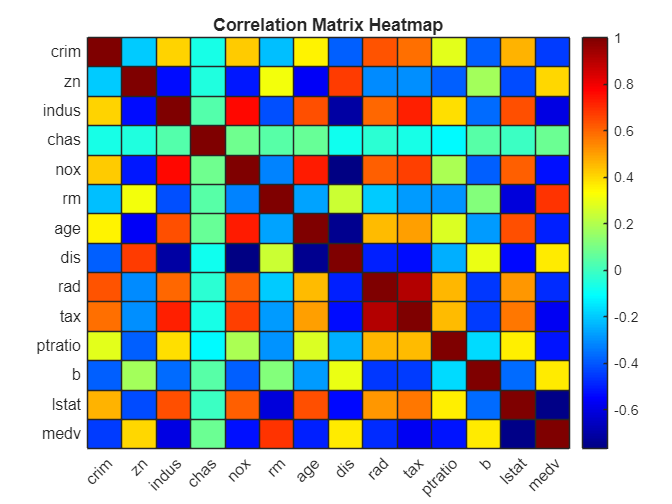

% Create the heatmap
figure;
h = heatmap(BostonHousing.Properties.VariableNames(1:end), ... % x-axis
            BostonHousing.Properties.VariableNames(1:end), ... % y-axis
            corrMatrix, ... % Correlation matrix data
            'Colormap', jet, ...
            'ColorbarVisible', 'on');
title('Correlation Matrix Heatmap');

## **Model Development**

BostonHousing = BostonHousing(BostonHousing.medv < 50.0, :);
% Check for missing values in the table
missingValues = ismissing(BostonHousing);
% Display missing values summary
missingSummary = sum(missingValues);
for i = 1:length(missingSummary)
    fprintf('%s: %d\n', BostonHousing.Properties.VariableNames{i}, missingSummary(i));
end

crim: 0
zn: 0
indus: 0
chas: 0
nox: 0
rm: 0
age: 0
dis: 0
rad: 0
tax: 0
ptratio: 0
b: 0
lstat: 0
medv: 0


% Data standardization
X = BostonHousing(:, 1:end-1); % Explanatory variables
X = table2array(X); 
Y = BostonHousing.medv; % Dependent variable
% Split data into 70% training, 15% validation, and 15% test sets
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
idx = cv.test;
% Separate into training and test data
XTrain = X(~idx, :);
YTrain = Y(~idx);
XTest = X(idx, :);
YTest = Y(idx);
% Further split the training data into training and validation sets
cv2 = cvpartition(size(XTrain, 1), 'HoldOut', 0.1765); % 15% of 70% is 10.5%
idx2 = cv2.test;
XValidation = XTrain(idx2, :);
YValidation = YTrain(idx2);
XTrain = XTrain(~idx2, :);
YTrain = YTrain(~idx2);

#### **Linear Regression**

%Train Linear Regression Model
linearModel = fitlm(XTrain, YTrain);

% Validate Linear Regression Model
YValidationPredLinear = predict(linearModel, XValidation);
validation_mse_linear = mean((YValidation - YValidationPredLinear).^2);

% Test Linear Regression Model
YTestPredLinear = predict(linearModel, XTest);
test_mse_linear = mean((YTest - YTestPredLinear).^2);
% Extract coefficients
coefficients = linearModel.Coefficients.Estimate;
% Extract variable names (including intercept)
variableNames = ['(Intercept)'; BostonHousing.Properties.VariableNames(1:end-1)'];
coeffTable = table(variableNames, coefficients, 'VariableNames', {'Variable', 'Coefficient'});
disp(coeffTable);

       Variable        Coefficient
    _______________    ___________

    {'(Intercept)'}        31.596 
    {'crim'       }     -0.016629 
    {'zn'         }      0.030146 
    {'indus'      }     -0.014289 
    {'chas'       }       0.41452 
    {'nox'        }       -11.699 
    {'rm'         }        3.4906 
    {'age'        }    -0.0087401 
    {'dis'        }       -1.1091 
    {'rad'        }       0.27224 
    {'tax'        }     -0.015216 
    {'ptratio'    }      -0.86599 
    {'b'          }      0.012353 
    {'lstat'      }      -0.40914 



%Let's evaluate the model's performance from test and validation sets
disp(['Test MSE for Linear Regression: ', num2str(test_mse_linear)]);

Test MSE for Linear Regression: 17.2812


disp(['Validation MSE for Linear Regression: ', num2str(validation_mse_linear)]);

Validation MSE for Linear Regression: 14.4236


#### **Decision Tree Regression**

% Define parameter grid
maxNumSplits_values = [5, 10, 20, 50, 100];
minLeafSize_values = [1, 5, 10, 20];
best_maxNumSplits = 0;
best_minLeafSize = 0;
best_validation_mse_tree = inf;

% Manual Grid Search for Decision Tree
for maxNumSplits = maxNumSplits_values
    for minLeafSize = minLeafSize_values
        % Train Decision Tree Model
        tree_model = fitrtree(XTrain, YTrain, 'MaxNumSplits', maxNumSplits, 'MinLeafSize', minLeafSize);
        
        % Validate Decision Tree Model
        YValidationPred = predict(tree_model, XValidation);
        validation_mse = mean((YValidation - YValidationPred).^2);
        
        % Update best parameters if current setting has lower validation MSE
        if validation_mse < best_validation_mse_tree
            best_validation_mse_tree = validation_mse;
            best_maxNumSplits = maxNumSplits;
            best_minLeafSize = minLeafSize;
        end
    end
end

% Train final Decision Tree model with best parameters
final_tree_model = fitrtree(XTrain, YTrain, 'MaxNumSplits', best_maxNumSplits, 'MinLeafSize', best_minLeafSize);

% Test Decision Tree Model
YTestPred = predict(final_tree_model, XTest);
test_mse_tree = mean((YTest - YTestPred).^2);

disp(['Best MaxNumSplits: ', num2str(best_maxNumSplits)]);

Best MaxNumSplits: 20


disp(['Best MinLeafSize: ', num2str(best_minLeafSize)]);

Best MinLeafSize: 5


disp(['Validation MSE for best Decision Tree model: ', num2str(best_validation_mse_tree)]);

Validation MSE for best Decision Tree model: 8.9238


disp(['Test MSE for best Decision Tree model: ', num2str(test_mse_tree)]);

Test MSE for best Decision Tree model: 11.7688


% Extract variable importance
variableImportance = predictorImportance(final_tree_model);
% Extract variable names (excluding the dependent variable 'medv')
variableNames = BostonHousing.Properties.VariableNames(1:end-1)';
%Let's create a table of variable importance
variableImportanceTable = table(variableNames, variableImportance', ...
        'VariableNames', {'Variable', 'Importance'});
disp(variableImportanceTable);

     Variable      Importance
    ___________    __________

    {'crim'   }     0.026141 
    {'zn'     }            0 
    {'indus'  }            0 
    {'chas'   }            0 
    {'nox'    }     0.033737 
    {'rm'     }      0.52146 
    {'age'    }            0 
    {'dis'    }      0.01375 
    {'rad'    }            0 
    {'tax'    }     0.048159 
    {'ptratio'}     0.031913 
    {'b'      }     0.010883 
    {'lstat'  }         1.78 



#### **Ridge Regression**

% Range of lambda values for Ridge Regression
lambda_values = logspace(-4, 4, 50); % 50 values between 10^-4 and 10^4
best_lambda = 0;
best_validation_mse_ridge = inf;

% Manual Grid Search for Ridge Regression
for lambda = lambda_values
    % Train Ridge Regression Model
    ridge_model = fitrlinear(XTrain, YTrain, 'Learner', 'leastsquares', 'Regularization', 'ridge', 'Lambda', lambda);
    
    % Validate Ridge Regression Model
    YValidationPred = predict(ridge_model, XValidation);
    validation_mse = mean((YValidation - YValidationPred).^2);
    
    % Update best lambda if current lambda has lower validation MSE
    if validation_mse < best_validation_mse_ridge
        best_validation_mse_ridge = validation_mse;
        best_lambda = lambda;
    end
end

% Train final Ridge Regression model with best lambda
final_ridge_model = fitrlinear(XTrain, YTrain, 'Learner', 'leastsquares', 'Regularization', 'ridge', 'Lambda', best_lambda);

% Test Ridge Regression Model
YTestPred = predict(final_ridge_model, XTest);
test_mse_ridge = mean((YTest - YTestPred).^2);

disp(['Best Lambda: ', num2str(best_lambda)]);

Best Lambda: 0.0001


disp(['Validation MSE for Ridge Regression model: ', num2str(best_validation_mse_ridge)]);

Validation MSE for Ridge Regression model: 45.8249


disp(['Test MSE for Ridge Regression model: ', num2str(test_mse_ridge)]);

Test MSE for Ridge Regression model: 44.1101


% Extract coefficients from Ridge Regression model
coefficients_ridge = final_ridge_model.Beta;
intercept_ridge = final_ridge_model.Bias;

% Combine the intercept and coefficients into one array
coefficients_ridge = [intercept_ridge; coefficients_ridge];

% Extract feature names including intercept
VariableNames = [{'Intercept'}, BostonHousing.Properties.VariableNames(1:end-1)];

% Create a table for better readability
coeffTable_ridge = table(VariableNames(:), coefficients_ridge, ...
    'VariableNames', {'Variable', 'Coefficient'});
disp(coeffTable_ridge);

      Variable       Coefficient
    _____________    ___________

    {'Intercept'}         21.371
    {'crim'     }     -0.0010078
    {'zn'       }      0.0030171
    {'indus'    }     -0.0011388
    {'chas'     }     1.0221e-05
    {'nox'      }    -4.6384e-06
    {'rm'       }     0.00036369
    {'age'      }     -0.0025564
    {'dis'      }     0.00034368
    {'rad'      }    -0.00084003
    {'tax'      }       -0.01822
    {'ptratio'  }     0.00011561
    {'b'        }       0.020854
    {'lstat'    }     -0.0017169



#### **Model Evaluation and Comparison**

% Collect performance metrics for comparison
models = {'Linear Regression', 'Decision Tree', 'Ridge Regression'};
validation_mse_values = [validation_mse_linear, best_validation_mse_tree, best_validation_mse_ridge];
test_mse_values = [test_mse_linear, test_mse_tree, test_mse_ridge];

% Display the results in a table
T = table(models', validation_mse_values', test_mse_values', 'VariableNames', {'Model', 'Validation MSE', 'Test MSE'});
disp(T);

            Model            Validation MSE    Test MSE
    _____________________    ______________    ________

    {'Linear Regression'}        14.424         17.281 
    {'Decision Tree'    }        8.9238         11.769 
    {'Ridge Regression' }        45.825          44.11 



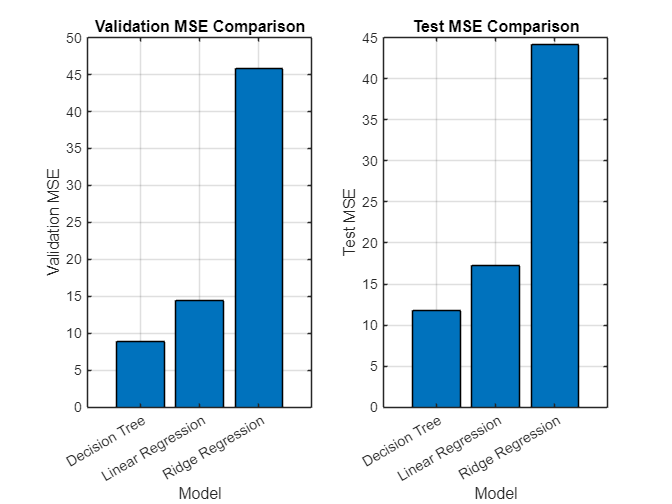

% Create the bar graph for comparison
figure;
subplot(1, 2, 1);
bar(categorical(models), validation_mse_values);
xlabel('Model');
ylabel('Validation MSE');
title('Validation MSE Comparison');
grid on;

subplot(1, 2, 2);
bar(categorical(models), test_mse_values);
xlabel('Model');
ylabel('Test MSE');
title('Test MSE Comparison');
grid on;